clear all;close all;

basePath = 'C:\Users\sgrc-325\Desktop\git\pipes\data\p test\';

% fileNames = {'1225_13P.CSV'};  %squar
% fileNames = {'1226_0P.CSV'};  %stop
% fileNames = {'1226_6P.CSV'};  %stop
% fileNames = {'1227_0P.CSV'};  %num fix 40 sqaur
% fileNames = {'1227_1P.CSV'};  %stop
% fileNames = {'0102_19P.CSV'};  %erro
fileNames = {   %multiple data
    '0102_16P.CSV', ...
    '0102_17P.CSV', ...
    '0102_18P.CSV', ...
    '0102_19P.CSV', 
    };
allData = [];

for i = 1:length(fileNames)
    filePath = fullfile(basePath, fileNames{i});
    tempData = readtable(filePath, 'Delimiter', ',', 'ReadVariableNames', false);
    allData = [allData; tempData]; % 將每個表格資料合併
end


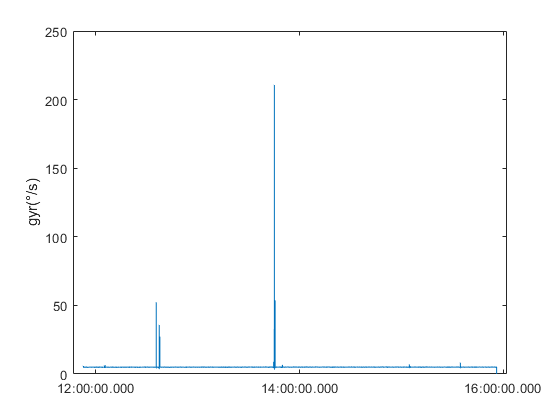

moData=allData;

% moData=allData(2000:end,:); %1227_0P.CSV
% moData=allData(100:end,:); %1227_1P
% moData=allData(2500:3200,:);
mo=[moData.Var1 moData.Var1 moData.Var1 moData.Var4 moData.Var5 moData.Var6 moData.Var7 moData.Var8 moData.Var9 moData.Var10 moData.Var11 moData.Var12 moData.Var13 moData.Var14 moData.Var15 moData.Var16 moData.Var17 moData.Var18 moData.Var19];

[No,~]=size(mo);

t= moData.Var1;
time_rtc=moData.Var2;
time_gps=moData.Var3;
m = mo(:,4:6);
acc1 = mo(:,7:9);
gyr1=mo(:,10:12);
lat=mo(:,13);
lon=mo(:,14);
alt=mo(:,15);
sats=mo(:,16);
fix=mo(:,17);
acc=mo(:,18);
tem=mo(:,19);

ax1=acc1(:,1);ay1=acc1(:,2);az1=acc1(:,3);
gx1=gyr1(:,1);gy1=gyr1(:,2);gz1=gyr1(:,3);
mx=m(:,1);my=m(:,2);mz=m(:,3);
aG=sqrt(ax1.^2+ay1.^2+az1.^2);
GG=sqrt(gyr1(:,1).^2+gyr1(:,2).^2+gyr1(:,3).^2);
mm4=sqrt(m(:,1).^2+m(:,2).^2+m(:,3).^2);
stdd=std(mo)'; %看標準差

close all
% tt = time_rtc;
tt = time_gps;

figure(1)
plot(tt,GG)
ylabel('gyr(°/s)');

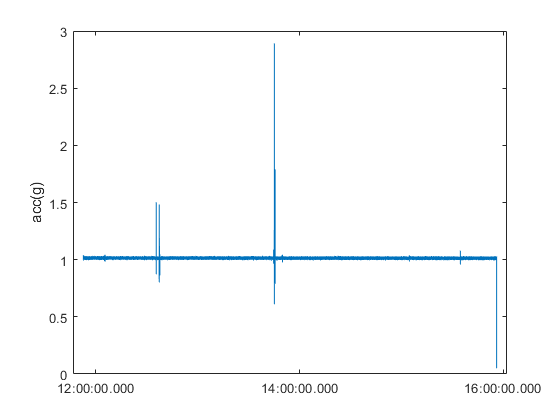

figure(2)
plot(tt,aG)
ylabel('acc(g)');

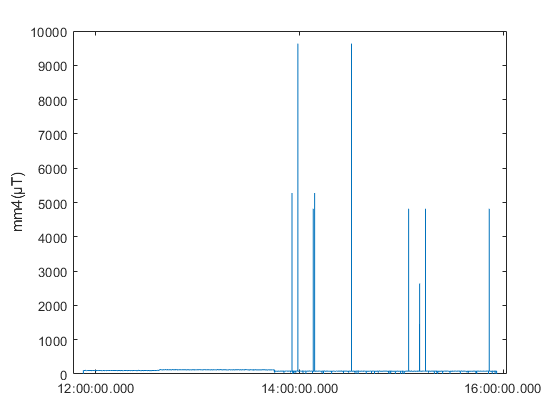

figure(3)
plot(tt,mm4)
ylabel('mm4(µT)');

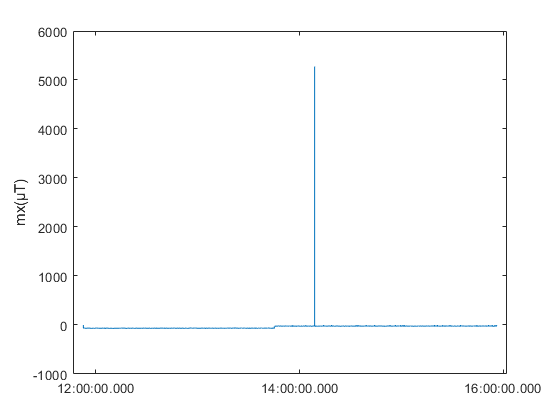


figure(4)
plot(tt,m(:,1))
ylabel('mx(µT)');

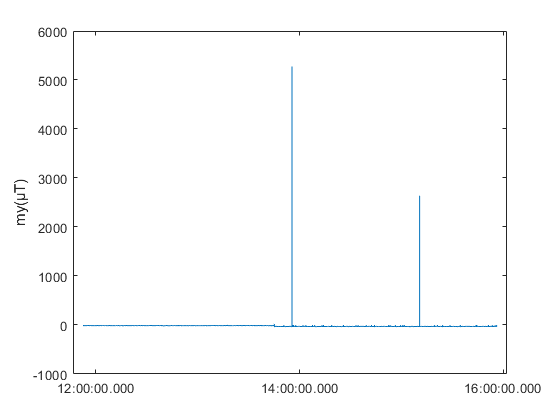

figure(5)
plot(tt,m(:,2))
ylabel('my(µT)');

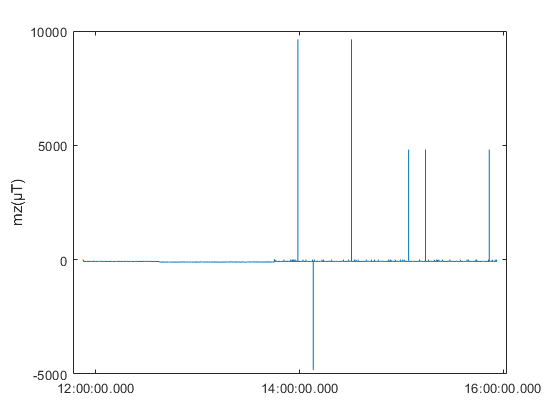

figure(6)
plot(tt,m(:,3))
ylabel('mz(µT)');

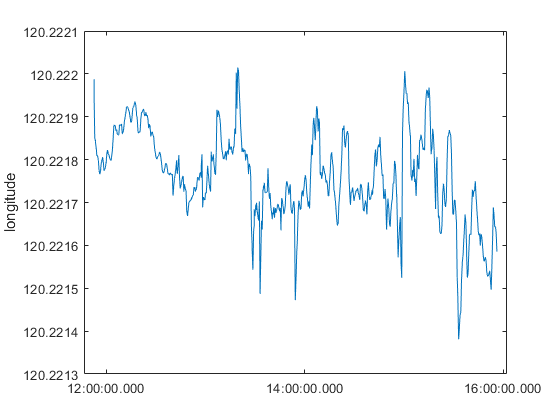


figure(7)
plot(tt,lon)
ylabel('longitude');

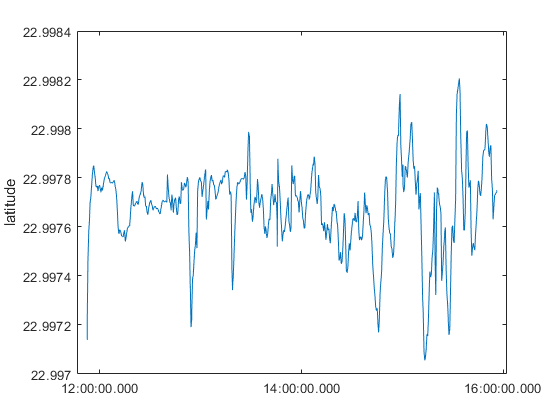

figure(8)
plot(tt,lat)
ylabel('latitude');

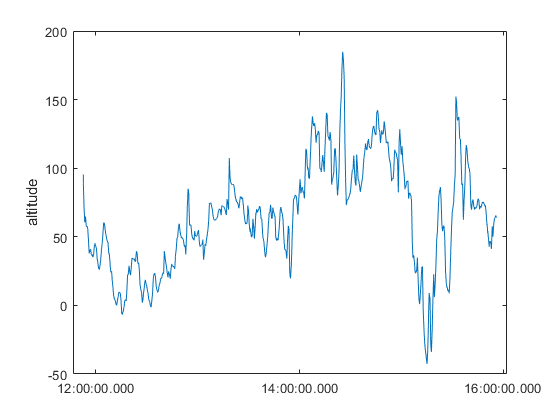

figure(9)
plot(tt,alt)
ylabel('altitude');

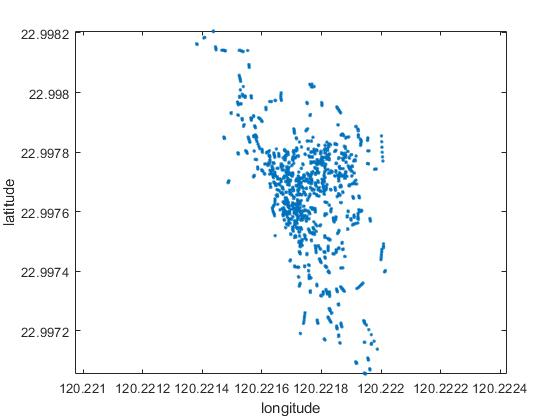

figure(10)
plot(lon,lat,'.')
xlabel('longitude');
ylabel('latitude');
axis equal;

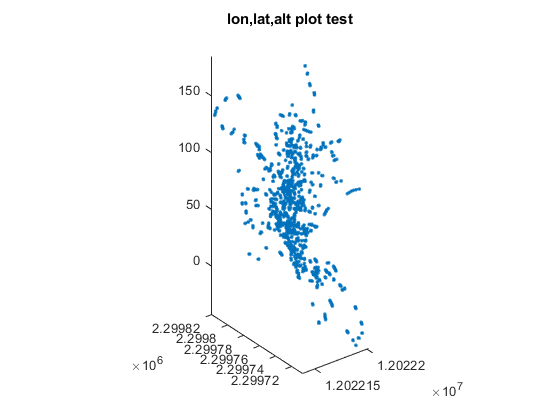

figure(11)
plot3(lon*100000,lat*100000,alt,'.')
title('lon,lat,alt plot test');
axis equal;

close all
% 設定投影參數，使用台灣西部二度分帶的 TWD97 座標系
latlon = [lat, lon]; % 經緯度資料組合為矩陣
twd97 = projcrs(3826); % TWD97 座標系

% 使用 projfwd 進行經緯度到座標的轉換
[x, y] = projfwd(twd97, latlon(:,1), latlon(:,2));

x=x*100; %m to cm
y=y*100;
altcm=alt*100;

x=x-x(1);
y=y-y(1);
altcm=altcm-altcm(1);
x1=[];y1=[];altcm1=[];

for i=1:No
    if(fix(i)>3)
        x1(end+1)=x(i);
        y1(end+1)=y(i);
        altcm1(end+1)=altcm(i);
    end
end

fprintf(['標準差 :\n' ...
    'x: %.3fcm,y :%.3fcm,alt: %.3fcm\n' ...
    '測試時長: %.2f 秒\n'], ...
    std(x),std(y),std(altcm),t(end));

標準差 :
x: 1064.450cm,y :1853.405cm,alt: 3873.760cm
測試時長: 18947.36 秒



fprintf('%s to %s\n', datestr(time_rtc(1)), datestr(time_rtc(end)));

11:52 AM to  5:08 PM


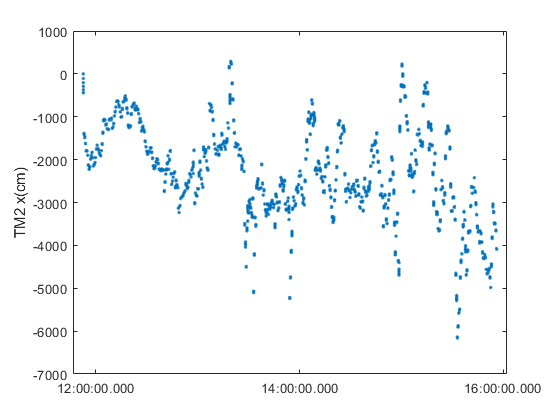


figure(2)
plot(tt,x,'.')
ylabel('TM2 x(cm)');

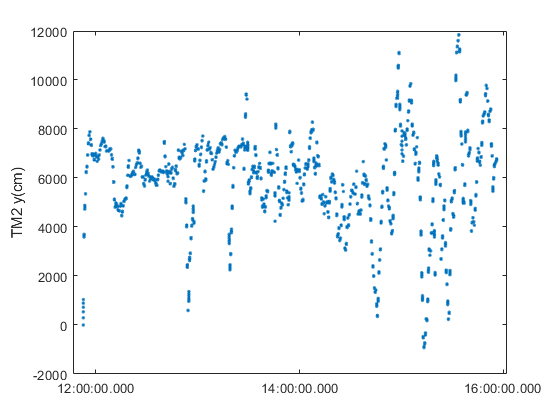

figure(3)
plot(tt,y,'.')
ylabel('TM2 y(cm)');

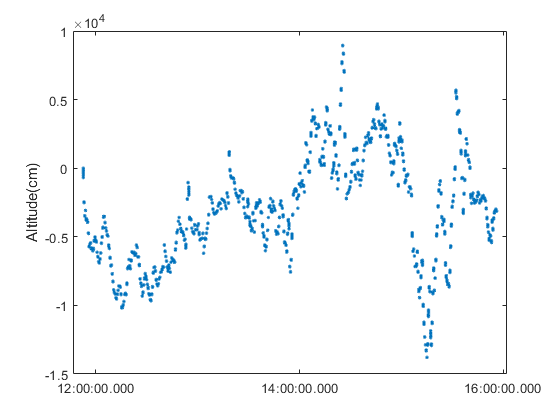

figure(4)
plot(tt,altcm1,'.')
ylabel('Altitude(cm)');

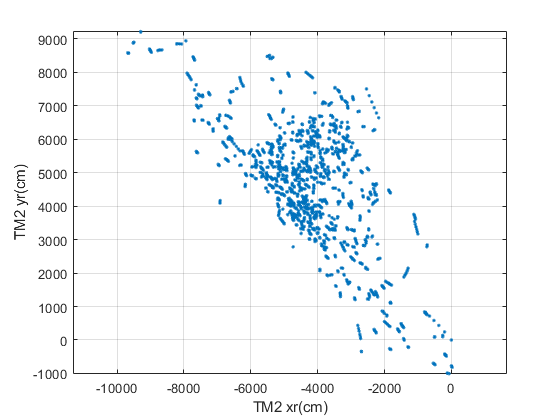


% figure(5)
% plot(x,y,'.')
% xlabel('TM2 x(cm)');
% ylabel('TM2 y(cm)');
% grid on;
% axis equal;
% 
% figure(6)
% plot3(x,y,altcm1,'.')
% xlabel('TM2 x(cm)');
% ylabel('TM2 y(cm)');
% zlabel('Altitude(cm)');
% grid on;
% axis equal;

% 設定旋轉角度（以度為單位）
theta_deg = 20;  % 旋轉角度設定為 30 度
theta = deg2rad(theta_deg);  % 轉換為弧度
R = [cos(theta), -sin(theta); sin(theta), cos(theta)];
rotated_coords = R * [x'; y'];
x_r = rotated_coords(1, :);
y_r = rotated_coords(2, :);

figure(7)
plot(x_r,y_r,'.')
xlabel('TM2 xr(cm)');
ylabel('TM2 yr(cm)');
grid on;
axis equal;

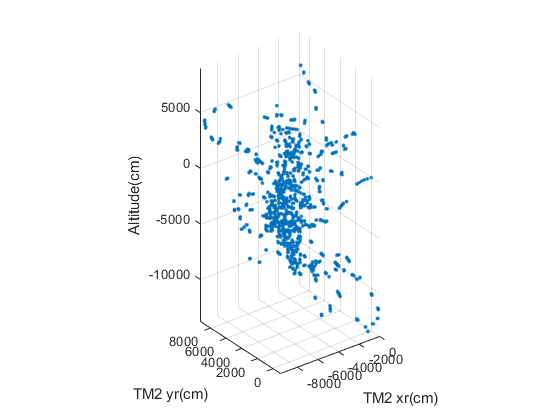


figure(8)
plot3(x_r,y_r,altcm1,'.')
xlabel('TM2 xr(cm)');
ylabel('TM2 yr(cm)');
zlabel('Altitude(cm)');
grid on;
axis equal;

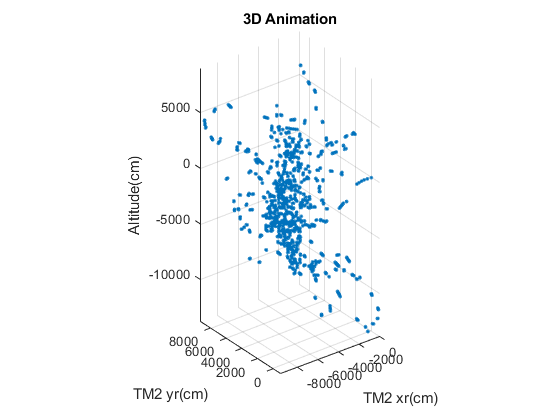

% 初始化圖形
close all

figure(9)
h = plot3(NaN, NaN, NaN, '.');  % 初始化一個空的點圖對象

% 設置圖形屬性
axis tight;  % 自動調整軸範圍
xlabel('TM2 xr(cm)');
ylabel('TM2 yr(cm)');
zlabel('Altitude(cm)');
title('3D Animation');
grid on;
axis equal;

% % 循環繪製每一幀
% for i = 1:length(x_r)
%     % 更新數據
%     set(h, 'XData', x_r(1:i), 'YData', y_r(1:i), 'ZData', altcm1(1:i));
%     view([0.0 90.0]) %俯視角
% %     view([-20.0 10.0]) %斜視角
% %     if mod(i, 50) == 0  % 每50幀更新一次
%         drawnow;
%     end
% end

set(h, 'XData', x_r, 'YData', y_r, 'ZData', altcm1);

drawnow;

% 計算所有點之間的最小距離

close all;
x=x_r;
y=y_r;
z=altcm1;

n = length(x);
min_distance = inf; % 初始設定為無限大
point1 = [0, 0, 0]; 
point2 = [0, 0, 0];
ii = 0;
jj = 0;

for i = 1:n
    for j = i+1:n
        dist = sqrt((x(i) - x(j))^2 + (y(i) - y(j))^2 + (z(i) - z(j))^2);
        if (dist < min_distance) && (dist ~= 0)
            min_distance = dist;
            ii = i;
            jj = j;
            point1 = [x(i), y(i), z(i)];
            point2 = [x(j), y(j), z(j)];
        end
    end
end

% 顯示最近兩點及其距離
fprintf('最近兩點的座標為 (%.3f, %.3f, %.3f) 和 (%.3f, %.3f, %.3f)\n', ...
    point1(1), point1(2), point1(3), point2(1), point2(2), point2(3));
fprintf('最近兩點之間的距離為 %.6f cm\n', min_distance);

% 3D 繪圖顯示最近兩點
figure(1)
hold on
plot3(x, y, z, '.'); % 繪製所有點
plot3(x(ii), y(ii), z(ii), 'ro'); % 最近點1
plot3(x(jj), y(jj), z(jj), 'go'); % 最近點2
plot3([x(ii), x(jj)], [y(ii), y(jj)], [z(ii), z(jj)], 'k-'); % 連接線

ak=1;
x_lim = [min(point1(1), point2(1)) - ak, max(point1(1), point2(1)) + ak];
y_lim = [min(point1(2), point2(2)) - ak, max(point1(2), point2(2)) + ak];
z_lim = [min(point1(3), point2(3)) - ak, max(point1(3), point2(3)) + ak];

grid on;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('3D Plot with Closest Points');
axis equal;
xlim(x_lim); % 設定 X 軸範圍
ylim(y_lim); % 設定 Y 軸範圍
zlim(z_lim); % 設定 Z 軸範圍
hold off;
